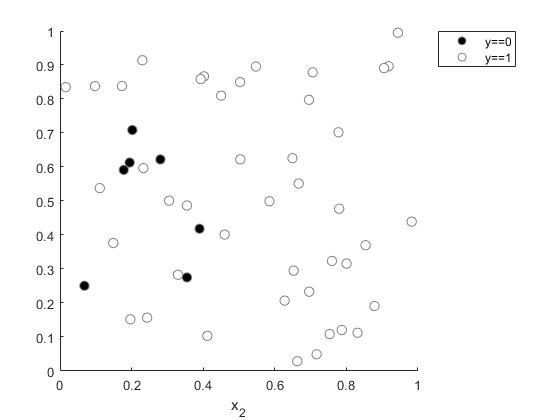

% generate simple data (50 data points defined in two dimensions;
% class assignment is 0 or 1 for each data point)

x1 = rand(50,1);
x2 = rand(50,1);

y = (3*x1 + x2 + randn(size(x1))) >1;


% visualize the data
figure; hold on;

h1 = scatter(x1(~y), x2(~y), 50,'k','filled');      % black dots for 0
h2 = scatter(x1(y), x2(y), 50,'w','filled');        % white dots for 1

set([h1 h2], 'MarkerEdgeColor', [.5 .5 .5]);
legend([h1 h2],{'y==0' 'y==1'},'Location','NorthEastOutside');
xlabel('x_1');
xlabel('x_2');

% define optimization options

options = optimset('Display','iter','FunValCheck','on',...
    'MaxFunEvals', Inf, 'MaxIter', Inf, ...
    'TolFun', 1e-6,'TolX',1e-6);


% define logistic fuction (this takes a matrix of values and applies the
% logistic function to each value)

logisticfun = @(x) 1./(1 + exp(-x));

% construct regressor matrix
x = [x1 x2];
x(:, end+1) =1; % we need to add a constant regressor

% define initial seed
params0 = zeros(1,size(x,2));

% define bounds
paramslb = []; % [] means no bound
paramsub = [];


$${(y* log(f(XW) + eps))} + 
(1-y)log(1 - f(XW) + eps)$$



% define cost function (negative-log-likehood)
    % here, the eps is a hack to ensure that the log returns a finite
    % number
costfunc = @(pp)     - sum((y.*log(logisticfun(x*pp') + eps)) + ...
    ((1-y) .* log(1-logisticfun(x*pp') + eps)));

% fit the logistic regression model by finding parameter values that
% minimize the cost function
[params, resnorm, residual, exitflag, output] = ...
    lsqnonlin(costfunc, params0, paramslb, paramsub, options)


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           4         1201.13             624         0.01
     1           8         361.179            30.2        0.001        1.50282
     2          16             315            60.1           10        2.41857
     3          21         270.118            8.59          100       0.586924
     4          25         267.659            9.55           10       0.117981
     5          29         251.857            11.9            1        1.00248
     6          35         249.994             5.7          100       0.124309
     7          39         249.152             5.1           10      0.0660648
     8          43         242.511            4.28            1       0.619724
     9          49         242.044            3.45          100      0.0519686
    10          53         241.652            3.44           10  

params =     6.3168    1.4052   -1.2480


resnorm = 233.2569

residual = 15.2728

exitflag = 3

output = struct with fields:
       iterations: 41
        funcCount: 198
         stepsize: 8.5924e-04
     cgiterations: []
    firstorderopt: 0.0359
        algorithm: 'levenberg-marquardt'
          message: 'Local minimum possible.↵↵lsqnonlin stopped because the final change in the sum of squares relative to ↵its initial value is less than the selected value of the function tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative sum of squares (r) is changing↵by less than options.FunctionTolerance = 1.000000e-06.↵↵Optimization Metric                                  Options↵relative change r =   4.57e-07             FunctionTolerance =   1e-06 (selected)'


% compute the  output (class assignment) of the model for each data point
modelfit = logisticfun(x*params') >=0.5;

% calculate percent correctn ( % of data points that are correctly
% classified by the model
pctcorrect = sum(modelfit==y) / length(y) * 100;


% visualize the model
    % prepare a grid of points to evaluate the model at

ax = axis;
xvals = linspace(ax(1),ax(2),100);
yvals = linspace(ax(3),ax(4),100);
[xx, yy] = meshgrid(xvals, yvals);


%  construct regressor matrix
X = [xx(:) yy(:) ];
X(:,end+1) = 1; % add a constant regressor at the end

% evaluate model at the points ( but don't perform the final thresholding)
outputimage = reshape( logisticfun(X*params'), [length(yvals) length(xvals)]);

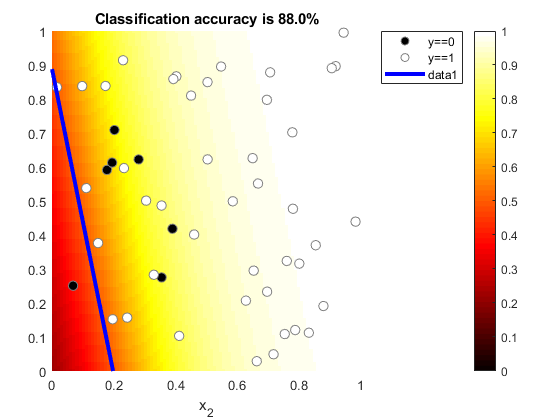

% visualize the image (the default coordinate system for images is 1:N
% where N is the number of pixels along each dimension. We have to move the
% image to the proper position; we accomplish this by setting XData and
% YData.)

h3 = imagesc(outputimage, [0 1]);   % the range of the logistic function is 0 to 1

set(h3,'XData',xvals, 'Ydata', yvals) % move upper in the middle of the image canvas

colormap(hot);
colorbar;

% visualize the decision boundary associated with the model by computing
% the 0.5-contour of the image

[c4, h4] = contour(xvals, yvals, outputimage, [.5 .5]);

set(h4,'LineWidth',3,'LineColor', [0 0 1]); % make the line thick and blue

    % send the image to the bottom so that we can see the data points
uistack(h3,'bottom');
    % restore the original axis range
axis(ax);
    % report hte accuract of the model in the title
title(sprintf('Classification accuracy is %.1f%%',pctcorrect))

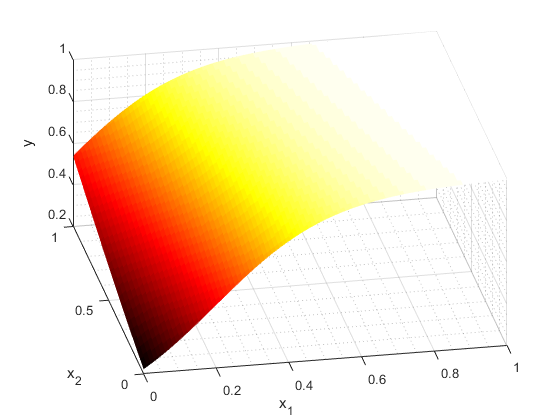

% try a 3D visualization
figure; hold on;
h1 = surf(xvals, yvals, outputimage);
set(h1, 'EdgeAlpha',0) % Don't show the edges of the surface
colormap(hot);

xlabel('x_1');
ylabel('x_2');
zlabel('y');

% set the viewing angle
view(-11, 42);

 % show some grid lines for reference 
set(gca,'XGrid','on','XMinorGrid','on', ...
    'YGrid','on','YMinorGrid','on', ...
     'ZGrid','on','ZMinorGrid','on');

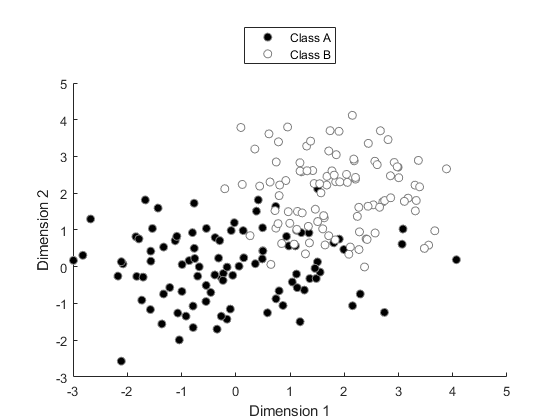

% Example 2. Compare solutions of different classifiers

% generate some data (two classes of data points defined in two dimensions)
classA = bsxfun(@times, [1.5 1]', randn(2,100));
classB = 2+randn(2,100);

% visualize the data
figure; hold on;

h1 = scatter(classA(1,:), classA(2,:),'ko','filled');
h2 = scatter(classB(1,:), classB(2,:),'wo','filled');

set([h1 h2],'MarkerEdgeColor', [.5 .5 .5]);
legend([h1 h2],{'Class A' 'Class B'},'Location','northoutside');
xlabel('Dimension 1');
ylabel('Dimension 2');

% prepare a grid of points to evaluate the model at
ax = axis;
xvals = linspace(ax(1), ax(2), 200);
yvals = linspace(ax(3), ax(4), 200);
[xx, yy] = meshgrid(xvals,yvals);
gridX = [xx(:) yy(:)];

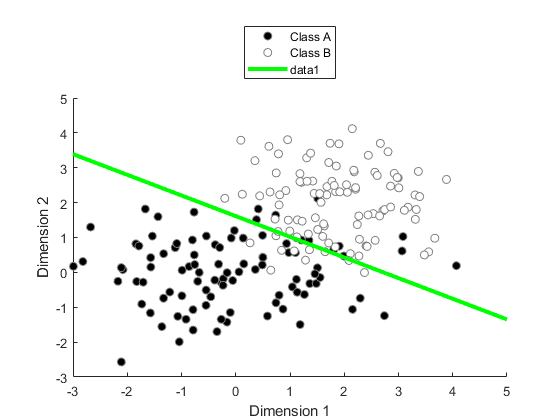

% perform logistic regression (here we use the MATLAB function glmfit.m
% instead of the direct implementation shown in Example 1)

X = [classA(1,:)' classA(2,:)' ;
    classB(1,:)' classB(2,:)'];
y = [zeros(size(classA,2),1); ones(size(classB,2),1)];

paramsA = glmfit(X,y,'binomial','link','logit');
outputimageA = glmval(paramsA,gridX,'logit');
outputimageA = reshape(outputimageA, [length(yvals) length(xvals)]);
[d,hA] = contour(xvals,yvals, outputimageA, [.5 .5]);
set(hA,'LineWidth',3,'LineColor', [0 1 0]); % make the line thick and green

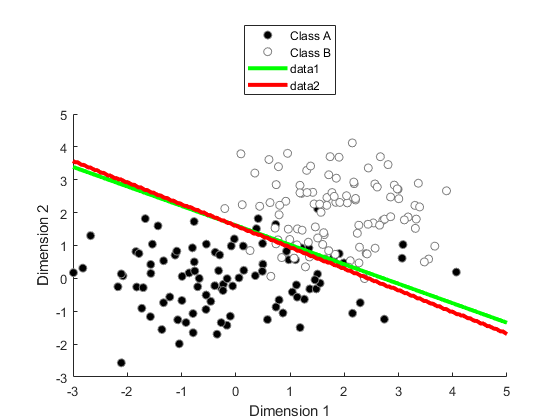

% perform linear discriminant analysis (here we use the MATLB function
% classify.m; ideally, we would implement it from scratch so we really
% understand how it works!)
outputimageB = classify(gridX, X,y,'linear');
outputimageB = reshape(outputimageB, [length(yvals) length(xvals)]);
[d,hB] = contour(xvals,yvals, outputimageB, [.5 .5]);

set(hB, 'LineWidth',3,'LineColor',[1 0 0]); % make the line thick and red

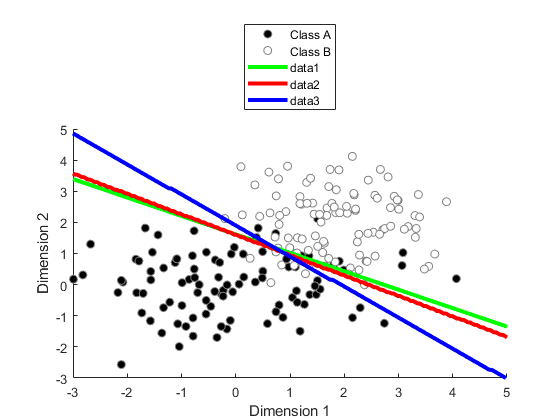

% perform nearest-prototype classification
centroidA = mean(classA,2); % 2 x 1
centroidB = mean(classB,2); % 2 x 1


% compute distance to centroid A
disttoA = sqrt(sum(bsxfun(@minus, gridX, centroidA').^2,2));
% compute distance to centroid B
disttoB = sqrt(sum(bsxfun(@minus, gridX, centroidB').^2,2));

outputimageC = disttoA > disttoB;
outputimageC = reshape(outputimageC,[length(xvals) length(yvals)]);
[d, hC] = contour(xvals, yvals, outputimageC, [.5 .5]); 
set(hC,'LineWidth',3,'LineColor',[0 0 1]);  % make the line thick and blue

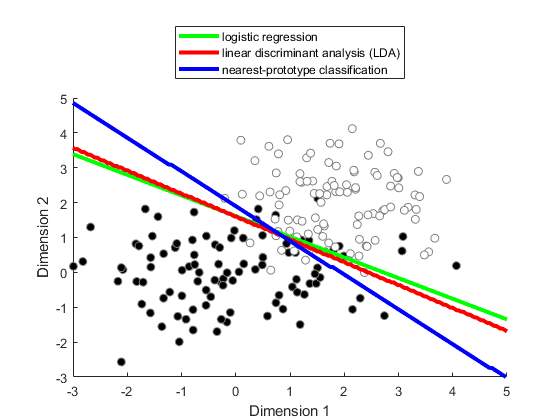


% add legend 
legend([hA hB hC],{'logistic regression'...
    'linear discriminant analysis (LDA)' ...  
    'nearest-prototype classification'}, ...   
    'Location','NorthOutside');